# nb20230711_134307_sharptrack2paxinos_sagittal.mlx

## 0 Place a mark at the optic fiber tip

addpath('\\ettina\Magill_Lab\Kouichi Nakamura\Analysis\allenCCFdata')
cd('\\ettina\Magill_Lab\Kouichi Nakamura\Analysis\Images from Otto\20230406 kms058') %TODO

subject_id = 'Paxinos_sagittal' %TODO

subject_id = 'Paxinos_sagittal'


% * remember to run one cell at a time, instead of the whole script at once *

% directory of histology images
image_folder = '\\ettina\Magill_Lab\Kouichi Nakamura\Analysis\Images from Otto\20230406 kms058\Paxinos sagittal';  %TODO


% directory to save the processed images -- can be the same as the above image_folder
% results will be put inside a new folder called 'processed' inside of this image_folder
save_folder = image_folder;

% name of images, in order anterior to posterior or vice versa
% once these are downsampled they will be named ['original name' '_processed.tif']
image_file_names = dirregexp(image_folder, '.+\_dots\.tif$'); % get the contents of the image_folder
image_file_names = natsortfiles({image_file_names.name});


disp(image_file_names')

    {'2023-07-11 11 40 35_dots.tif'}
    {'2023-07-11 11 40 59_dots.tif'}
    {'2023-07-11 11 41 11_dots.tif'}
    {'2023-07-11 11 41 40_dots.tif'}
    {'2023-07-11 11 41 48_dots.tif'}


% image_file_names = {'slide no 2_RGB.tif','slide no 3_RGB.tif','slide no 4_RGB.tif'}; % alternatively, list each image in order

% if the images are individual slices (as opposed to images of multiple
% slices, which must be cropped using the cell CROP AND SAVE SLICES)
image_files_are_individual_slices = true;

% use images that are already at reference atlas resolution (here, 10um/pixel)
use_already_downsampled_image = false; %TODO

% pixel size parameters: microns_per_pixel of large images in the image
% folder (if use_already_downsampled_images is set to false);
% microns_per_pixel_after_downsampling should typically be set to 10 to match the atlas
microns_per_pixel = 6.86 ; %TODO 
microns_per_pixel_after_downsampling = 10 ;%TODO



% ----------------------
% additional parameters
% ----------------------

% if the images are cropped (image_file_are_individual_slices = false),
% name to save cropped slices as; e.g. the third cropped slice from the 2nd
% image containing many slices will be saved as: save_folder/processed/save_file_name02_003.tif
save_file_name = [subject_id,'_'];

% increase gain if for some reason the images are not bright enough
gain = 1; 

% plane to view ('coronal', 'sagittal', 'transverse')
plane = 'sagittal'; %TODO

% size in pixels of reference atlas brain. For coronal slice, this is 800 x 1140
if strcmp(plane,'coronal')
    atlas_reference_size = [800 1140]; 
elseif strcmp(plane,'sagittal')
    atlas_reference_size = [800 1320]; 
elseif strcmp(plane,'transverse')
    atlas_reference_size = [1140 1320];
end






% finds or creates a folder location for processed images -- 
% a folder within save_folder called processed
folder_processed_images = fullfile(save_folder, 'processed');
if ~exist(folder_processed_images)
    mkdir(folder_processed_images)
end


% directory of histology
processed_images_folder = folder_processed_images; %TODO

% name the saved probe points, to avoid overwriting another set of probes going in the same folder
probe_save_name_suffix = '_paxinos'; %TODO

% directory of reference atlas files
annotation_volume_location = "\\ettina\Magill_lab\Kouichi Nakamura\Analysis\allenCCFdata\annotation_volume_10um_by_index.npy";
structure_tree_location = "\\ettina\Magill_lab\Kouichi Nakamura\Analysis\allenCCFdata\structure_tree_safe_2017.csv";
template_volume_location = "\\ettina\Magill_lab\Kouichi Nakamura\Analysis\allenCCFdata\template_volume_10um.npy";

% plane to view ('coronal', 'sagittal', 'transverse')
% plane = 'sagittal';


% load the reference brain and region annotations
if ~exist('av','var') || ~exist('st','var') || ~exist('tv','var')
    disp('loading reference atlas...')
    av = readNPY(annotation_volume_location);
    st = loadStructureTree(structure_tree_location);
    tv = readNPY(template_volume_location);
end

loading reference atlas...



% select the plane for the viewer
if strcmp(plane,'coronal')
    av_plot = av;
    tv_plot = tv;
elseif strcmp(plane,'sagittal')
    av_plot = permute(av,[3 2 1]);
    tv_plot = permute(tv,[3 2 1]);
elseif strcmp(plane,'transverse')
    av_plot = permute(av,[2 3 1]);
    tv_plot = permute(tv,[2 3 1]);
end

## 1. ENTER PARAMETERS AND FILE LOCATION

% subject_id = 'kms058' %TODO

% file location of object points
% save_folder = '\\ettin\Magill_Lab\Kouichi Nakamura\Analysis\Images from Otto\20230406 kms058\RGB2\processed'


% directory of reference atlas files
% annotation_volume_location = "\\ettin\Magill_lab\Kouichi Nakamura\Analysis\allenCCFdata\annotation_volume_10um_by_index.npy";
% structure_tree_location = "\\ettin\Magill_lab\Kouichi Nakamura\Analysis\allenCCFdata\structure_tree_safe_2017.csv";

% name of the saved object points
object_save_name_suffix = probe_save_name_suffix;% [subject_id,'_opticfiber_'];

% either set to 'all' or a list of indices from the clicked objects in this file, e.g. [2,3]
objects_to_analyze = 'all';

% plane used to view when points were clicked ('coronal' -- most common, 'sagittal', 'transverse')
% plane = 'sagittal';

% brain figure black or white
black_brain = true;


## 2. LOAD THE REFERENCE ANNOTATIONS AND PROBE POINTS


% load the reference brain annotations
if ~exist('av','var') || ~exist('st','var')
    disp('loading reference atlas...')
    av = readNPY(annotation_volume_location);
    st = loadStructureTree(structure_tree_location);
end


% load object points
objectPoints = load(fullfile(save_folder, 'processed',['probe_points' object_save_name_suffix]));

% determine which objects to analyze
if strcmp(objects_to_analyze,'all')
    objects = 1:size(objectPoints.pointList.pointList,1);
else
    objects = objects_to_analyze;
end 

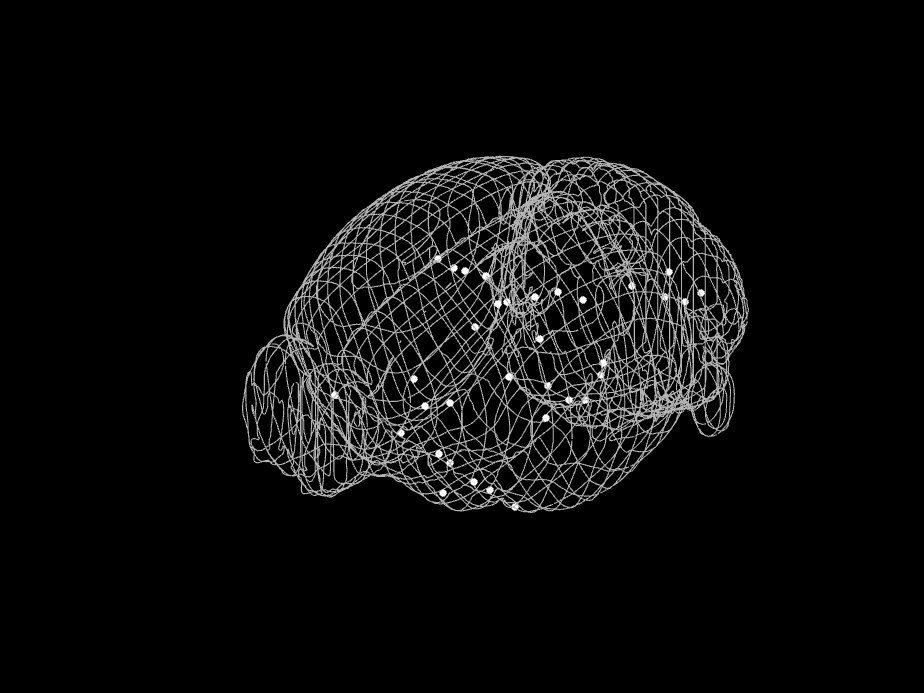

Clicked points for object 1


                           name                               acronym       AP_location    DV_location    ML_location    avIndex 
    ___________________________________________________    _____________    ___________    ___________    ___________    ________
    {'Secondary motor area layer 1'                   }    {'MOs1'     }        0.38          0.87           -0.42       {[  26]}
    {'Striatum'                                       }    {'STR'      }        1.18          4.14           -0.42       {[ 572]}
    {'Medial habenula'                                }    {'MH'       }       -1.82          2.89           -0.42       {[ 713]}
    {'root'                                           }    {'root'     }       -3.15          5.86           -0.42       {[   1]}
    {'optic chia

%% BRING UP THE RELEVANT DATA FOR EACH PROBE POINTS, FOR FURTHER ANALYSIS

% initialize cell array containing info on each clicked point
if length(objects) > 1
    roi_annotation = cell(length(objects),1);
    roi_location = cell(length(objects),1);
end

% generate needed values
bregma = allenCCFbregma(); % bregma position in reference data space
atlas_resolution = 0.010; % mm

% plot brain grid
ProbeColors = [1 1 1; 1 .75 0;  .3 1 1; .4 .6 .2; 1 .35 .65; .7 .7 1; .65 .4 .25; .7 .95 .3; .7 0 0; .6 0 .7; 1 .6 0]; 
% order of colors: {'white','gold','turquoise','fern','bubble gum','overcast sky','rawhide', 'green apple','purple','orange','red'};
fwireframe = plotBrainGrid([], [], [], black_brain); hold on; 
fwireframe.InvertHardcopy = 'off';



for object_num = objects
    
    selected_object = objects(object_num);
        
    % get the object points for the currently analyzed object    
    if strcmp(plane,'coronal')
        curr_objectPoints = objectPoints.pointList.pointList{selected_object,1}(:, [3 2 1]);
    elseif strcmp(plane,'sagittal')
        curr_objectPoints = objectPoints.pointList.pointList{selected_object,1}(:, [1 2 3]);
    elseif strcmp(plane,'transverse')
        curr_objectPoints = objectPoints.pointList.pointList{selected_object,1}(:, [1 3 2]);
    end

    % plot points on the wire frame brain
    figure(fwireframe); hold on
    hp = plot3(curr_objectPoints(:,1), curr_objectPoints(:,3), curr_objectPoints(:,2), '.','linewidth',2, 'color',[ProbeColors(object_num,:) .2],'markers',10);   

    % use the point's position in the atlas to get the AP, DV, and ML coordinates
    ap = -(curr_objectPoints(:,1)-bregma(1))*atlas_resolution;
    dv = (curr_objectPoints(:,2)-bregma(2))*atlas_resolution;
    ml = (curr_objectPoints(:,3)-bregma(3))*atlas_resolution;

    roi_location_curr = [ap dv ml];
    
    % initialize array of region annotations
    roi_annotation_curr = cell(size(curr_objectPoints,1),3);    
    
    % loop through every point to get ROI locations and region annotations
    for point = 1:size(curr_objectPoints,1)

        % find the annotation, name, and acronym of the current ROI pixel
        ann = av(curr_objectPoints(point,1),curr_objectPoints(point,2),curr_objectPoints(point,3));
        name = st.safe_name{ann};
        acr = st.acronym{ann};

        roi_annotation_curr{point,1} = ann;
        roi_annotation_curr{point,2} = name;
        roi_annotation_curr{point,3} = acr;

    end
    
    % save results in cell array
    if length(objects) > 1
        roi_annotation{object_num} = roi_annotation_curr;
        roi_location{object_num} = roi_location_curr;
    else
        roi_annotation = roi_annotation_curr;
        roi_location = roi_location_curr;
    end
 
    % display results in a table
    disp(['Clicked points for object ' num2str(selected_object)])
    roi_table = table(roi_annotation_curr(:,2),roi_annotation_curr(:,3), ...
                        roi_location_curr(:,1),roi_location_curr(:,2),roi_location_curr(:,3), roi_annotation_curr(:,1), ...
         'VariableNames', {'name', 'acronym', 'AP_location', 'DV_location', 'ML_location', 'avIndex'});
     disp(roi_table)
    
end



% now, use roi_location and roi_annotation for your further analyses

## Prepare coordinates from Paxinos

vns = { 'VariableNames', {'AP_location','DV_location','ML_location', 'figure'}};


mat_PaFr = [...
    0.013, 0.014, 0.36, 104;...
    -1.021, 2.893, 0.36, 104;...
    2.183, 1.933, 0.36, 104;...
    3.603, 4.772, 0.36, 104;...
    0.113, 5.821, 0.36, 104;...
    6.301, 2.993, 0.36, 104;...
    -0.014, -0.140, 1.32, 112;...
    0.213, 1.433, 1.32, 112;...
    -1.556, 2.993, 1.32, 112;...
    -0.014, 5.734, 1.32, 112;...
    3.002, 1.533, 1.32, 112;...
    2.582, 4.725, 1.32, 112;...
    3.869, 4.625, 1.32, 112;...
    6.348, 2.8, 1.32, 112;...
    -0.013, 0.2791, 2.4, 121;...
    1.3748, 1.7750, 2.4, 121;...
    -2.2571, 3.5939, 2.4, 121;...
    0.2918, 6.0171, 2.4, 121;...
    3.4690, 3.2109, 2.4, 121;...
    6.7419, 2.5588, 2.4, 121;...
    -0.0013, -0.1487, 1.8, 116;...
    -0.4391, 2.819, 1.8, 116;...
    -3.2028, 3.0109, 1.8, 116;...
    -0.3017, 5.8606, 1.8, 116;...
    3.0577, 1.6706, 1.8, 116;...
    3.5799, 3.9545, 1.8, 116;...
    6.3701, 2.9914, 1.8, 116;...
    -0.0013, -0.1487, 0.84, 108;...
    -0.3017, 3.3484, 0.84, 108;...
    -0.6717, 5.7725, 0.84, 108;...
    -4.3217, 1.5706, 0.84, 108;...
    2.6271, 1.6706, 0.84, 108;...
    3.7394, 4.8796, 0.84, 108;...
    6.9603, 2.7535, 0.84, 108;...
    ]

mat_PaFr =     0.0130    0.0140    0.3600  104.0000
   -1.0210    2.8930    0.3600  104.0000
    2.1830    1.9330    0.3600  104.0000
    3.6030    4.7720    0.3600  104.0000
    0.1130    5.8210    0.3600  104.0000
    6.3010    2.9930    0.3600  104.0000
   -0.0140   -0.1400    1.3200  112.0000
    0.2130    1.4330    1.3200  112.0000
   -1.5560    2.9930    1.3200  112.0000
   -0.0140    5.7340    1.3200  112.0000



PaFr = array2table(mat_PaFr, vns{:});

PaFr.AP_location = PaFr.AP_location * -1;


## DV

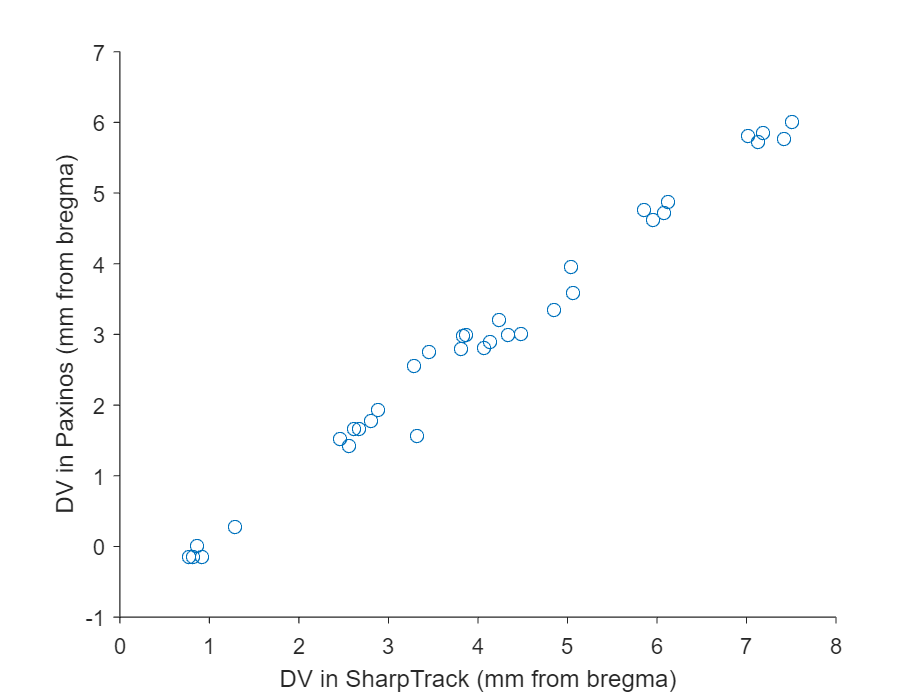

figure
ax = axes;
plot(roi_table.DV_location, PaFr.DV_location, 'o')
box off;
tickdir out;
xlabel('DV in SharpTrack (mm from bregma)')
ylabel('DV in Paxinos (mm from bregma)')


X = [ones(size(roi_table.DV_location)) , roi_table.DV_location];
Y = PaFr.DV_location;
b_DV = X\Y

b_DV =    -0.8335
    0.9211


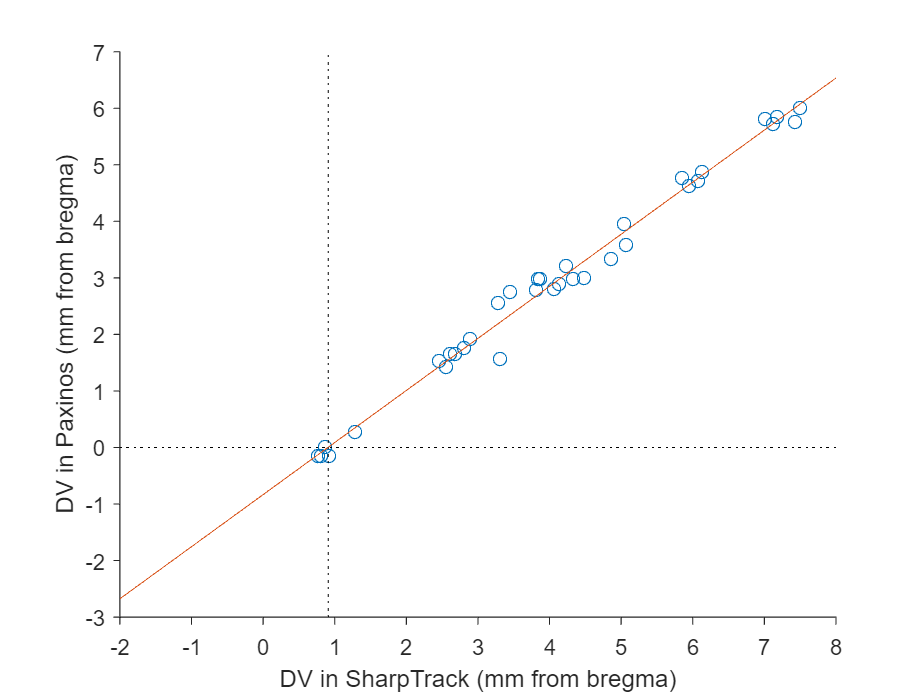


x = -2:0.01:8; % 10 micron
y = b_DV(1) + b_DV(2) * x;

hold on
ax.XTick = -2:8;
plot(x, y);
plot(xlim, [0 0], 'k:')
plot([x(find(y >=0,1,"first")), x(find(y >=0,1,"first"))], ylim, 'k:')

fprintf("At y = 0, i.e. the real bregma, SharpTrack DV value is %.3f mm\n", x(find(y >=0,1,"first")));

At y = 0, i.e. the real bregma, SharpTrack DV value is 0.910 mm


fprintf("SharpTrack depth x can be converted to Paxinos depth by y = %.3f * x %+.3f\n", b_DV(2), b_DV(1));

SharpTrack depth x can be converted to Paxinos depth by y = 0.921 * x -0.834


## AP

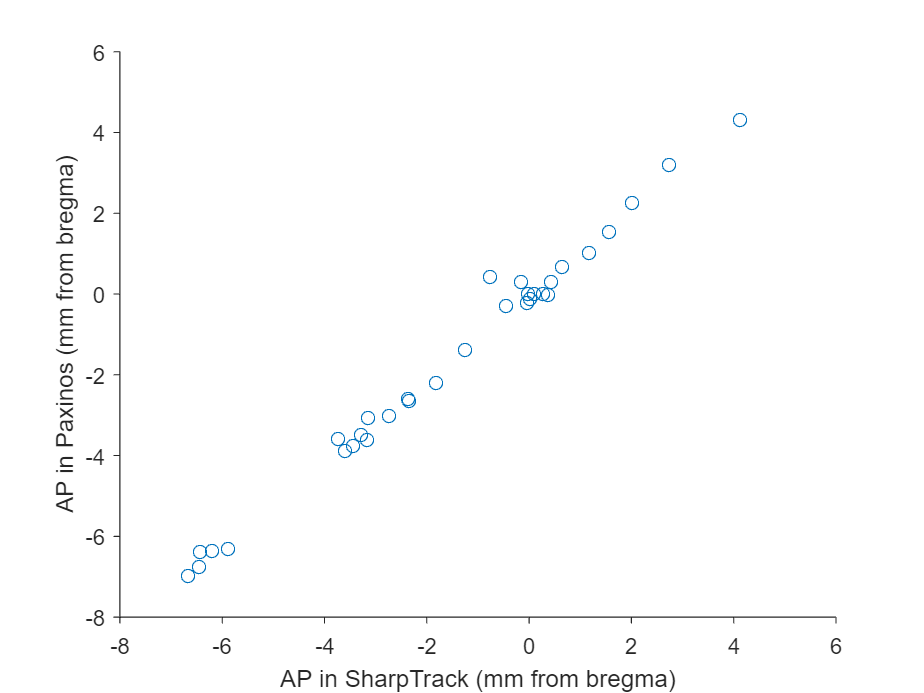

figure
ax = axes;
plot(roi_table.AP_location, PaFr.AP_location, 'o')
box off;
tickdir out;
xlabel('AP in SharpTrack (mm from bregma)')
ylabel('AP in Paxinos (mm from bregma)')


X = [ones(size(roi_table.AP_location)) , roi_table.AP_location];
Y = PaFr.AP_location;
b_AP = X\Y

b_AP =    -0.0084
    1.0418


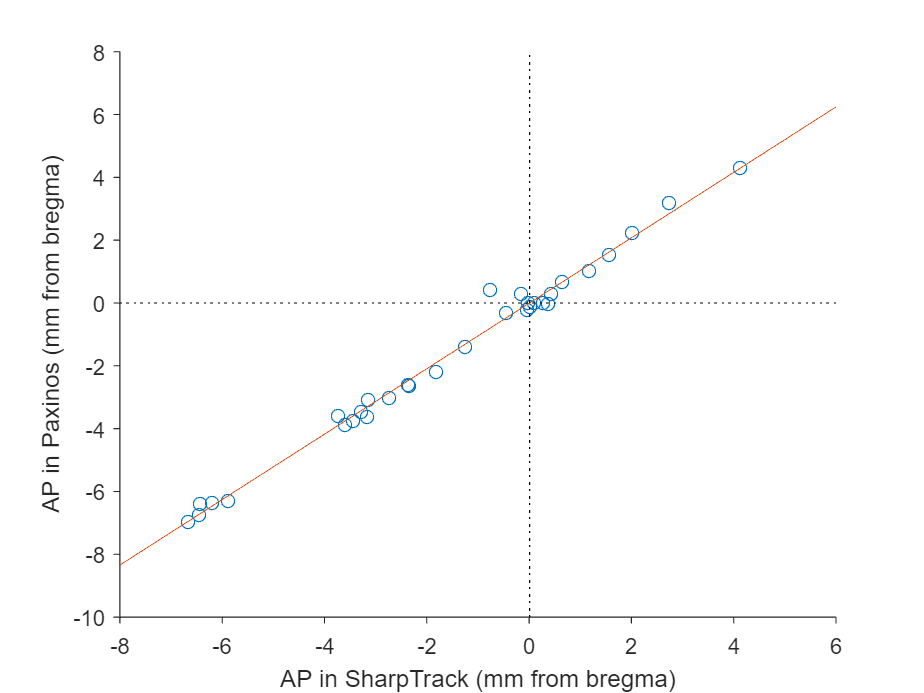


x = -8:0.01:6; % 10 micron
y = b_AP(1) + b_AP(2) * x;

hold on
plot(x, y);
plot(xlim, [0 0], 'k:')
plot([x(find(y >=0,1,"first")), x(find(y >=0,1,"first"))], ylim, 'k:')

fprintf("At y = 0, i.e. the real bregma, SharpTrack AP value is %.3f mm\n", x(find(y >=0,1,"first")));

At y = 0, i.e. the real bregma, SharpTrack AP value is 0.010 mm


fprintf("SharpTrack AP x can be converted to Paxinos AP by y = %.3f * x %+.3f\n", b_AP(2), b_AP(1));

SharpTrack AP x can be converted to Paxinos AP by y = 1.042 * x -0.008


## ML

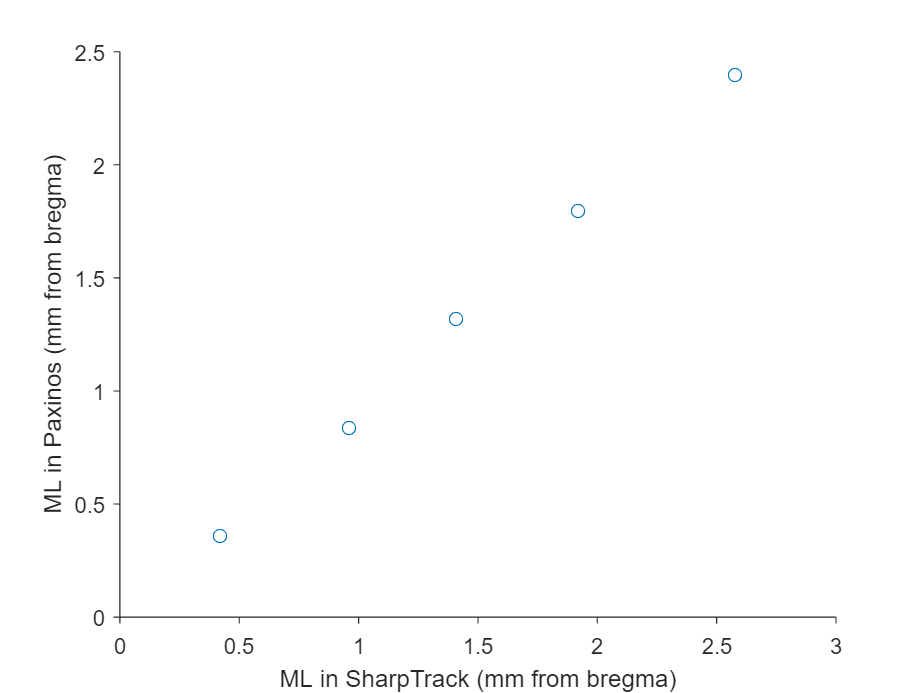

figure
ax = axes;
plot(roi_table.ML_location * -1, PaFr.ML_location, 'o')
box off;
tickdir out;
xlabel('ML in SharpTrack (mm from bregma)')
ylabel('ML in Paxinos (mm from bregma)')


X = [ones(size(roi_table.ML_location)) , roi_table.ML_location * -1];
Y = PaFr.ML_location;
b_ML = X\Y

b_ML =    -0.0466
    0.9544


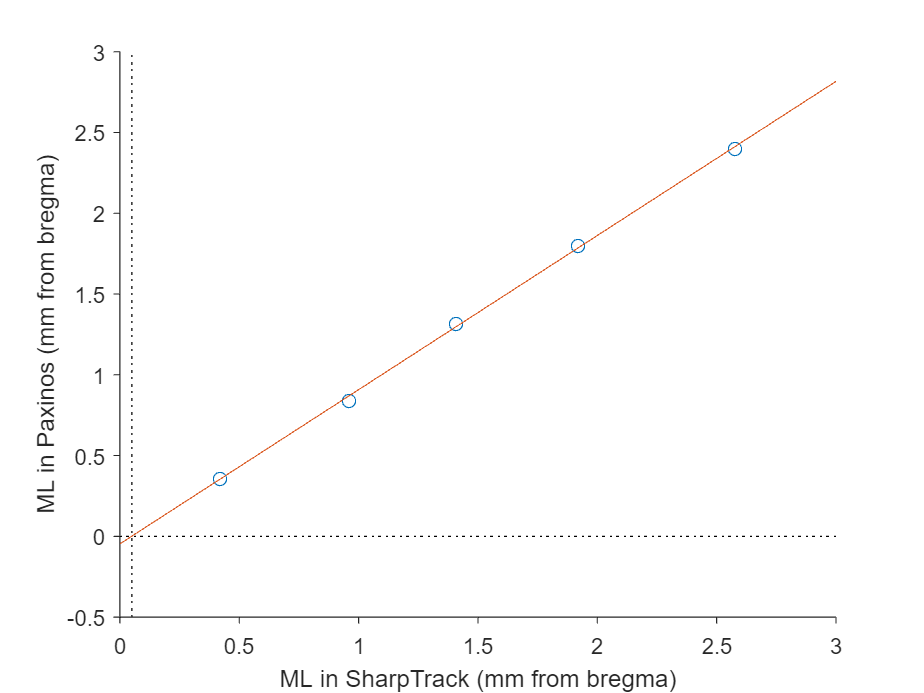


x = 0:0.01:3; % 10 micron
y = b_ML(1) + b_ML(2) * x;

hold on
plot(x, y);
plot(xlim, [0 0], 'k:')
plot([x(find(y >=0,1,"first")), x(find(y >=0,1,"first"))], ylim, 'k:')

fprintf("At y = 0, i.e. the real bregma, SharpTrack ML value is %.3f mm\n", x(find(y >=0,1,"first")));

At y = 0, i.e. the real bregma, SharpTrack ML value is 0.050 mm


fprintf("SharpTrack ML x can be converted to Paxinos ML by y = %.3f * x %+.3f\n", b_ML(2), b_ML(1));

SharpTrack ML x can be converted to Paxinos ML by y = 0.954 * x -0.047
